# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 12-Mar-2024 09:56:53

## Load Network Parameters

Load network parameters like weights, biases, or layers unusupported for network code generation from the the stored parameters file.

params = load("C:\Users\PAVAN KUMAR REDDY\OneDrive\Documents\MATLAB\params_2024_03_12__09_56_32.mat");

## Create Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","data","Mean",params.data.Mean)
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4],"Bias",params.conv1.Bias,"Weights",params.conv1.Weights)
    clippedReluLayer(3,"Name","clippedrelu")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    globalMaxPooling2dLayer("Name","gmpool_2")
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.conv2.Bias,"Weights",params.conv2.Weights)
    clippedReluLayer(3,"Name","clippedrelu_1")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    globalMaxPooling2dLayer("Name","gmpool_1")
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv3.Bias,"Weights",params.conv3.Weights)
    clippedReluLayer(3,"Name","clippedrelu_2")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv4.Bias,"Weights",params.conv4.Weights)
    clippedReluLayer(3,"Name","clippedrelu_3")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv5.Bias,"Weights",params.conv5.Weights)
    clippedReluLayer(3,"Name","clippedrelu_4")
    globalMaxPooling2dLayer("Name","gmpool")
    fullyConnectedLayer(10,"Name","fc")
    clippedReluLayer(3,"Name","clippedrelu_5")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(10,"Name","fc_1")
    clippedReluLayer(3,"Name","clippedrelu_6")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(10,"Name","fc_2")
    rpnSoftmaxLayer("Name","rpn-softmax")
    rpnClassificationLayer("Name","rpn-classification")];

## Plot Layers

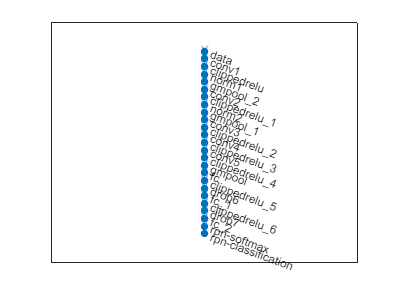

plot(layerGraph(layers));

net = assembleNetwork(layers);

Error using assembleNetwork
Unrecognized method, property, or field 'ClassNames' for class 'nnet.cnn.layer.RPNClassificationLayer'.

Caused by:
    Unrecognized method, property, or field 'ClassNames' for class 'nnet.cnn.layer.RPNClassificationLayer'.